## Introduction

In this script, i try to add the potenetial to observe the property

Also the change the history part is changed into a more easy form. 

## Data Importing

import parameters

m=1;%just for test
psi=1;
zeta=1;
H=0.5;
kB=1;
T=1;

import Time interval

delta=0.01;

import Total TIme

Tmax=10;

import Total_experiment_number

Total_experiment_number=100000;

## Main loop

initialization

imax=Tmax/delta;
v=zeros(Total_experiment_number,imax+1);
x=zeros(Total_experiment_number,imax+1);
a=zeros(Total_experiment_number,imax+1);

loop

for n=1:Total_experiment_number
    v(n,1)=normrnd(0,(kB*T/m)*0.5);%should be random;
    x(n,1)=0;%no need to be random
    a(n,1)=0;%no need to be random
    BH=wfbm(H,imax+1);
    for i=1:imax
        x(n,i+1)=x(n,i)+v(n,i)*delta;
        v(n,i+1)=v(n,i)+a(n,i)*delta;
        a(n,i+1)=-zeta*v(n,i)/m-psi*x(n,i)+(2*zeta*kB*T)^0.5*(BH(i+1)-BH(i))/delta;%ODE
    end
end

## Output and plotting

averageX=zeros(imax+1,1);
RMSX=zeros(imax+1,1);
for i=1:imax+1
    averageX(i,1)=sum(x(:,i))/Total_experiment_number;
    RMSX(i,1)=sum(x(:,i).^2)/Total_experiment_number-averageX(i,1)^2;
end

plotting

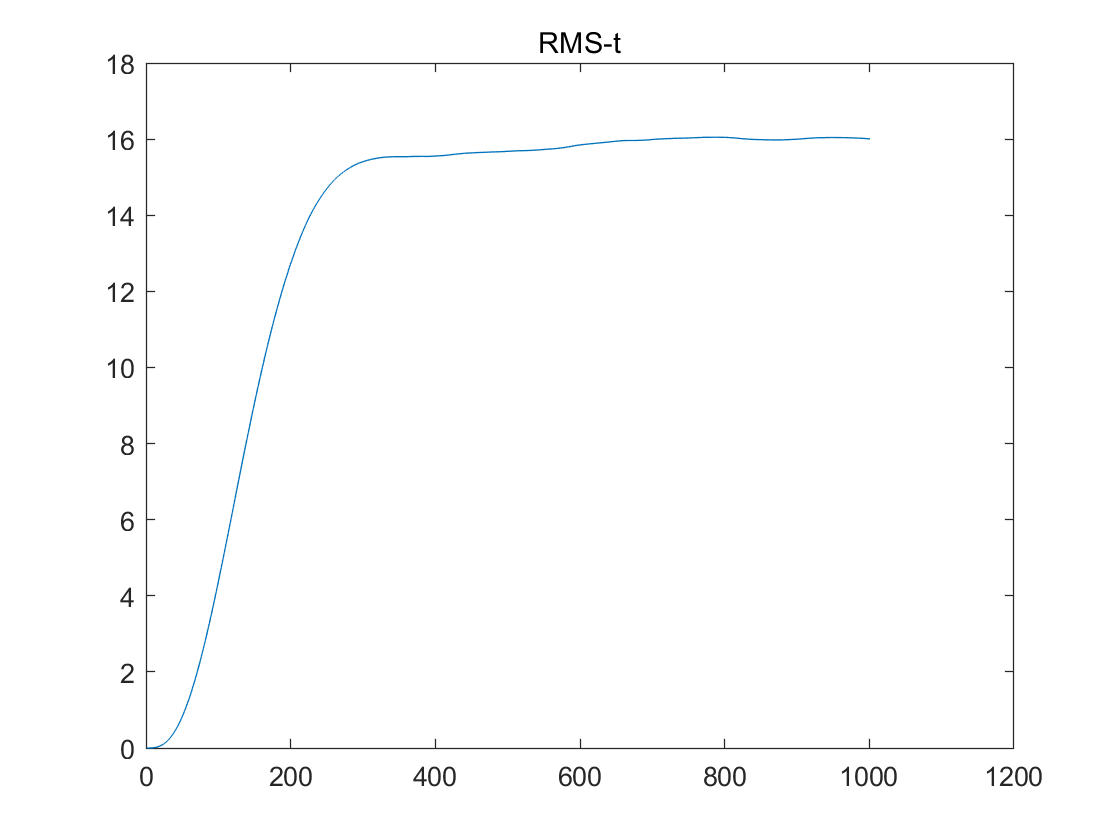

figure
plot(RMSX)
title('RMS-t')

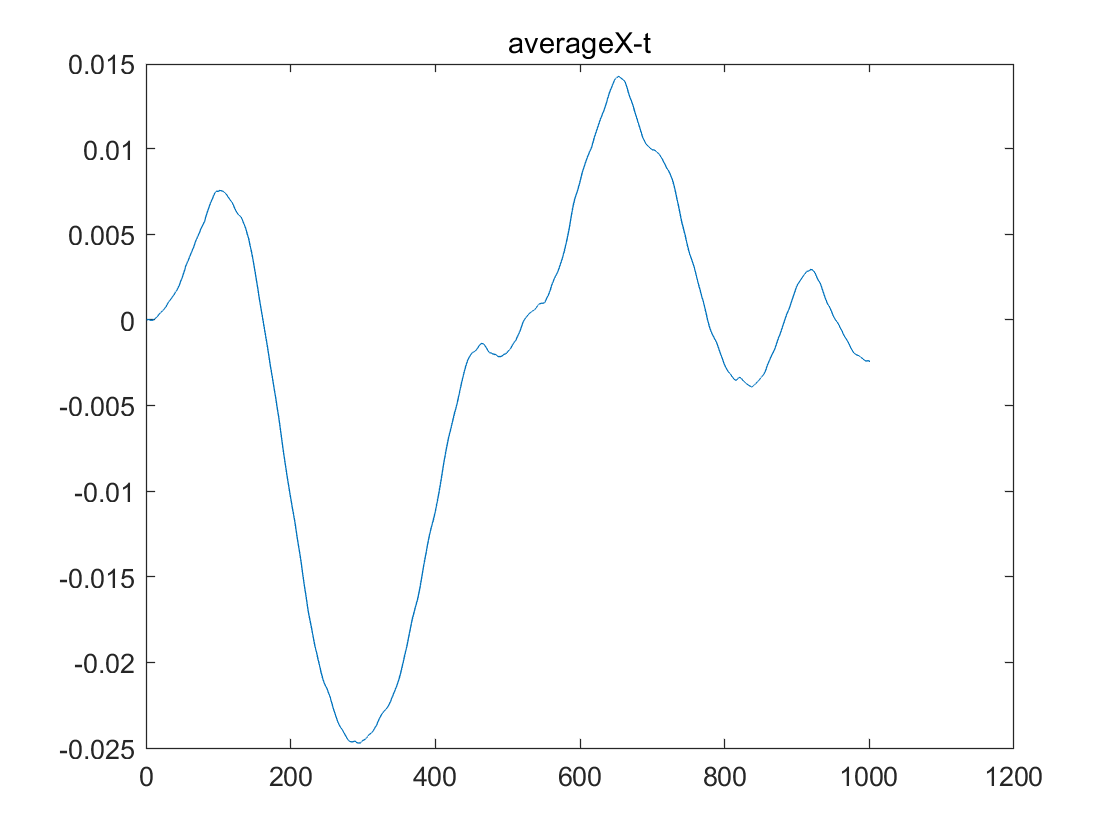

figure
plot(averageX)
title('averageX-t')